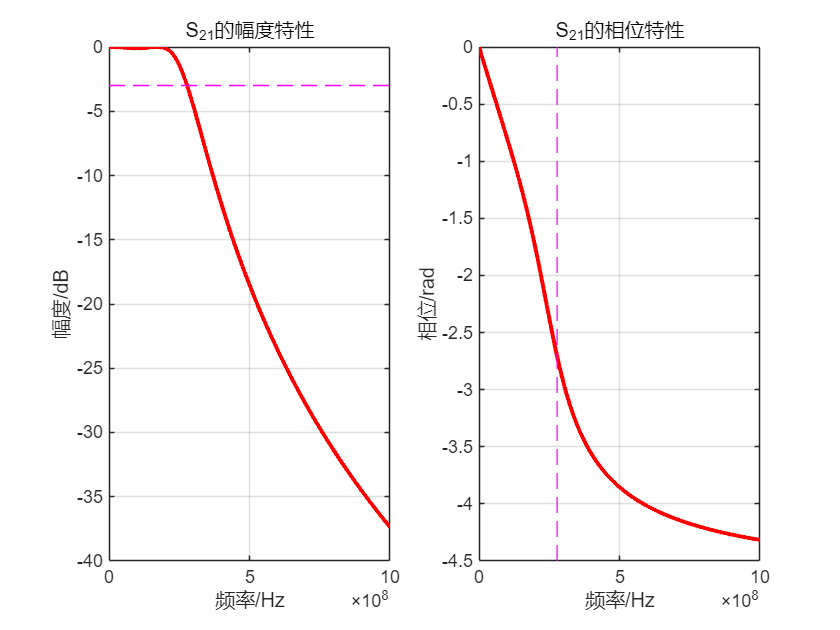

clc
clear

L1=45.6e-9;
C1=16.4e-12;
Z0=50;
fmin=0;
fmax=1e9;
fstep=1e6;
f=fmin:fstep:fmax;
w=2*pi*f;

a11=1-L1*C1*w.^2;
a12=1i*w*L1/Z0;
a21=(2*1i*w*C1-1i.*w.^3*L1*C1.^2)*Z0;
a22=1-w.^2*L1*C1;
S21=2./(a11+a12+a21+a22);
S11=1./(a11+a12+a21+a22).*(a11+a12-a21-a22);
subplot(1,2,1);
plot(f,20*log10(abs(S21)),'Color','r','LineWidth',2);
xlim=get(gca,'XLim');
hold on;
plot(xlim,[-3,-3],'m--');
xlabel('频率/Hz');
ylabel('幅度/dB');
title('S_{21}的幅度特性');
grid on;
hold off;

subplot(1, 2, 2);
plot(f, phase(S21), 'Color', 'r', 'LineWidth', 2);
ylim2=get(gca,'YLim');
hold on;
plot([0.278e9,0.278e9],ylim2,'m--');
xlabel('频率/Hz');
ylabel('相位/rad');
title('S_{21}的相位特性');
grid on;
hold off;

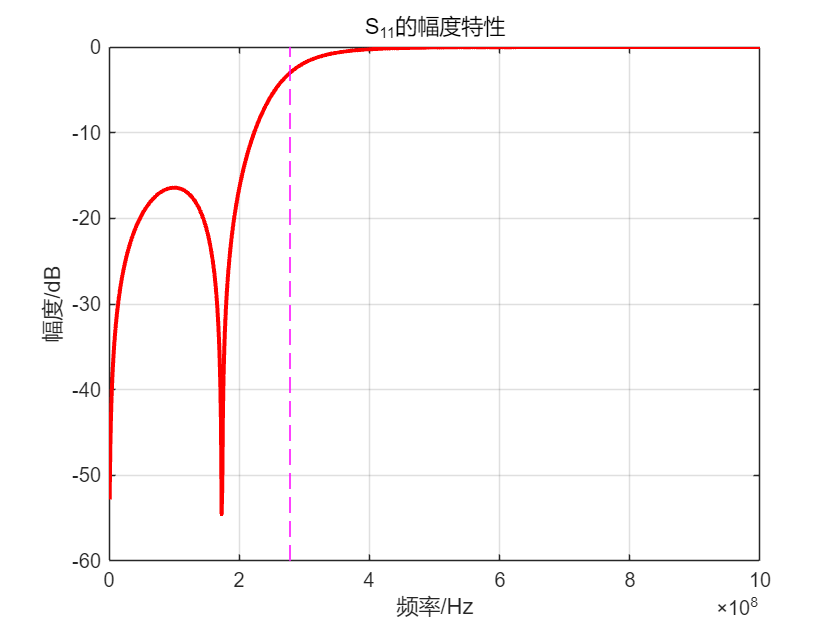


figure(2);
plot(f, 20 * log10(abs(S11)), 'Color', 'r', 'LineWidth', 2);
ylim2=get(gca,'YLim');
hold on;
plot([0.278e9,0.278e9],ylim2,'m--');
xlabel('频率/Hz');
ylabel('幅度/dB');
title('S_{11}的幅度特性');
grid on;
hold off;